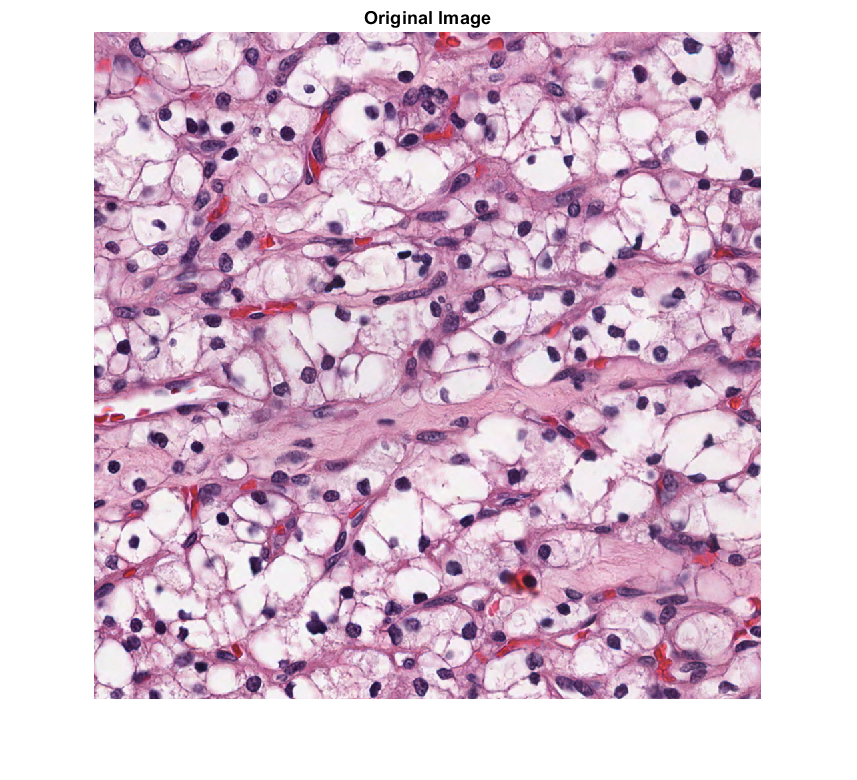

clc;
clearvars;
rgbimage = imread("im3.tif");
[H,E] = Deconvolution(rgbimage);
H = imlocalbrighten(H,1);
E = imlocalbrighten(E,1);

% Display
imshow(rgbimage);title("Original Image")

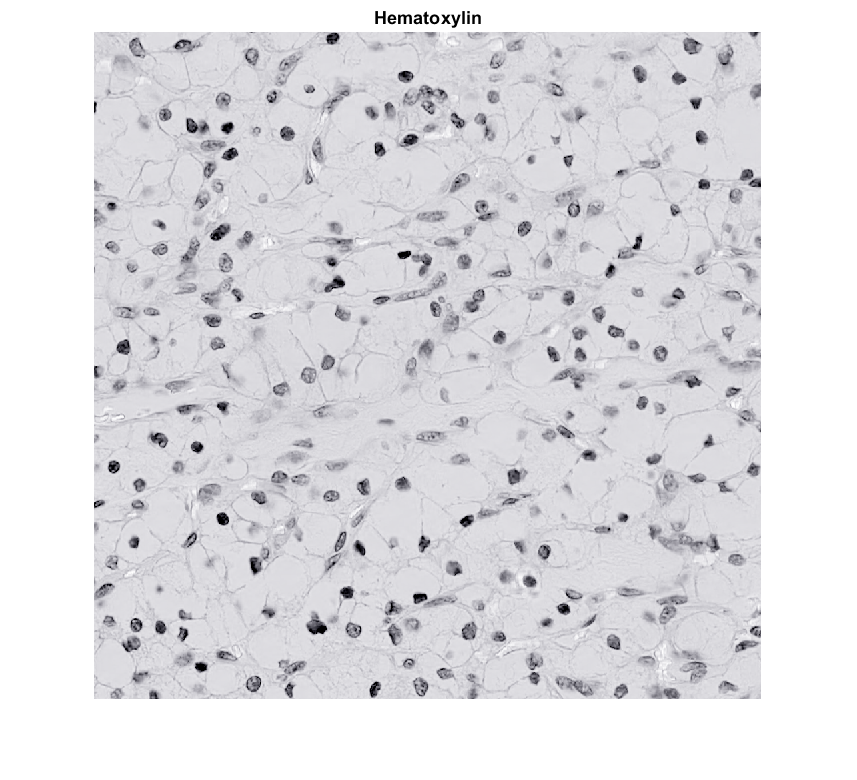

figure;
imshow(H,[]);title("Hematoxylin");

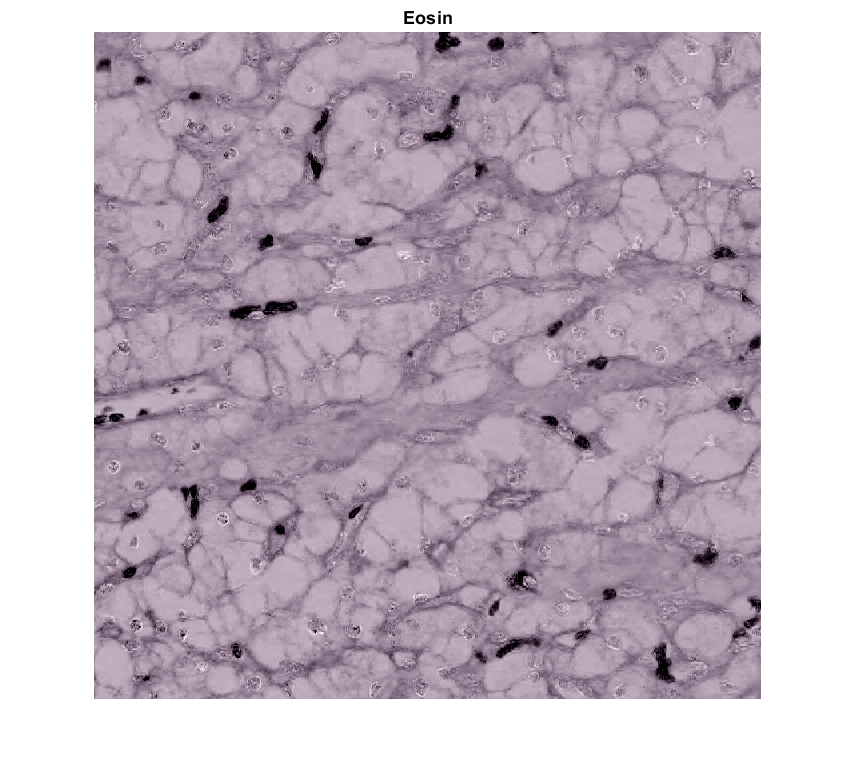

imshow(E,[]);title("Eosin");

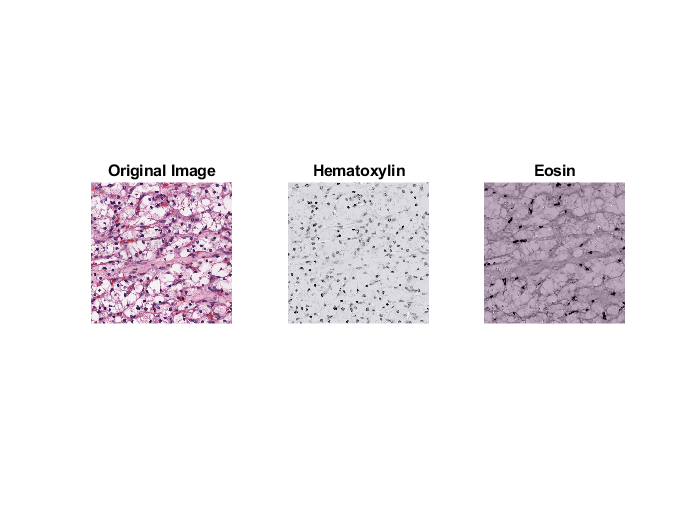

figure;
subplot(131),imshow(rgbimage);title("Original Image");
subplot(132),imshow(H,[]);title("Hematoxylin");
subplot(133),imshow(E,[]);title("Eosin");

function [H,E] = Deconvolution(rgbimage)   
        % Deconvolution Function applies stain deconvolution to an image
        % and breaks it into 3 planes of Hematoxilin ,Eosin and Diaminobenzidine(DAB)
        % After the color deconvolution process, images are reconstructed for each stain separately
        % This can be achieved by adding zeros matrix to the rest of the channel of Hematoxylin,Eosin and Diaminobenzidine(DAB)  
        % Image is multiplied with colour deconvolution matrix to get 3 different planes of stains
        % For reconstruction of image of different stains , normalized Optical Density matrix is used
        % Transformation has to be normalized in order to get correct balancing of  absorbtion factor for each separate stain.
        
        % Set of Optical Density (OD) values referred from research paper named "Quantification of histochemical staining by color deconvolution "
        He = [0.18; 0.20; 0.08];
        Eo = [0.01; 0.13; 0.01];
        DAB = [0.10; 0.21; 0.29];
        
        % Normalizing OD matrix to achieve correct balancing of the absorbtion factor for each separate stain
        hed2rgb = [He/norm(He) Eo/norm(Eo) DAB/norm(DAB)]';

        % Color deconvolution matrix is the inverse of OD matrix
        rgb2hed = inv(hed2rgb) ; 

        % Convert input image to double precision float
        % add 1 to avoid any errors due to log transformations
        rgbimage = double(rgbimage)+1;
        OD = -log(rgbimage);
        
        % Multiplying with Colour deconvolution matrix to separate images of different stains
        DCop = reshape(OD,[],3) *rgb2hed;
        DCop = reshape(DCop, size(rgbimage));
        
        % Normalizing matrix
        DCop = normalz(DCop);
        
        % Create an RGB image for each of the stains by adding null value in rest
        % of the 2 channels out of 3 channels
        s = size(rgbimage);
        A(:,:,1) = DCop(:,:,1);A(:,:,2) = zeros(s(1),s(2));A(:,:,3) = zeros(s(1),s(2));
        B(:,:,1) = zeros(s(1),s(2));B(:,:,2) = DCop(:,:,2);B(:,:,3) = zeros(s(1),s(2));

        % Convert input image to double precision float
        % add 1 to avoid any erros due to log transformation
        Dop1 = double(A)+1;
        OD1 = -log(Dop1)+1;
        Dop2 = double(B)+1;
        OD2 = -log(Dop2)+1;
        
        % Multiplication with Optical denisty matrix  to reconstruct image
        % of different stain
		H = -reshape(OD1,[],3) *hed2rgb;
        E = -reshape(OD2,[],3) *hed2rgb;
        
        % Applying exponential function for reconstruction
        H = -exp(H);
	    H = reshape(H, size(DCop));
        E = -exp(E);
		E = reshape(E, size(DCop));
        
        % Normalizing matrix
		H = normalz(H);
		E = normalz(E); 
end


function Iop = normalz(Iin)                  % Normalization Function
	    Iop = Iin;  
	    for i=1:size(Iin,3)
		Channel = Iop(:,:,i);
        % Converting image intensties in between 0 and 1 
		Iop(:,:,i) = (Iop(:,:,i)-min(Channel(:)))/(max(Channel(:)-min(Channel(:))));
        % invert image
        Iop(:,:,i) = 1 - Iop(:,:,i);
     end
end


